# Actividad 2.2 (Parametrización de trayectorias)

Para hacer la parametrización de estas figuras definimos un conjunto de puntos equiespaciados en un círculo y luego conectarlos para formar una figura con NNN lados. Para lograr esto, lo primero que se hace es dividir el círculo completo de 2π2\pi2π radianes en NNN segmentos, lo que se consigue con `linspace(0, 2*pi, N+1)`. Aquí, N+1N+1N+1 se usa para que el primer y el último punto coincidan, cerrando la figura. Luego, cada uno de estos puntos se convierte de coordenadas polares a cartesianas usando las fórmulas x=rcos (θ)x = r \cos(\theta)x=rcos(θ) y y=rsin (θ)y = r \sin(\theta)y=rsin(θ). Al cambiar el valor de NNN, modificamos la cantidad de puntos generados, lo que afecta la cantidad de lados de la figura

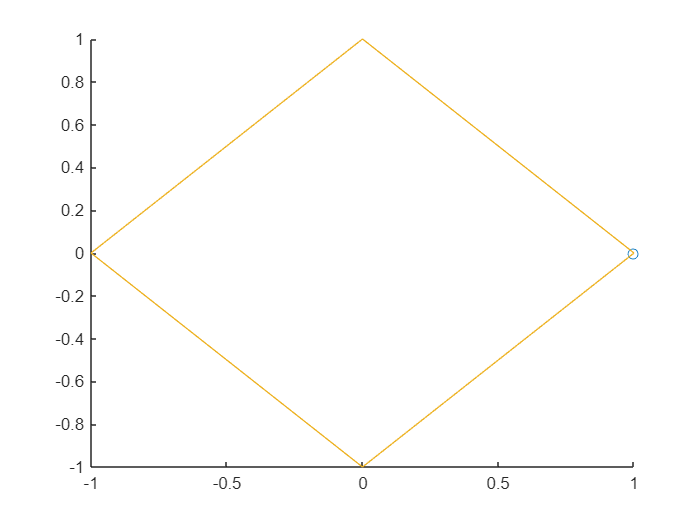

clc
clear all

theta = [0, pi/2, pi, 3*pi/2, 2*pi]; % Ángulos para un cuadrado
r = ones(size(theta)); % Radios constantes
x = r .* cos(theta);
y = r .* sin(theta);

% Graficamos la trayectoria
figure(1)
comet(x, y)

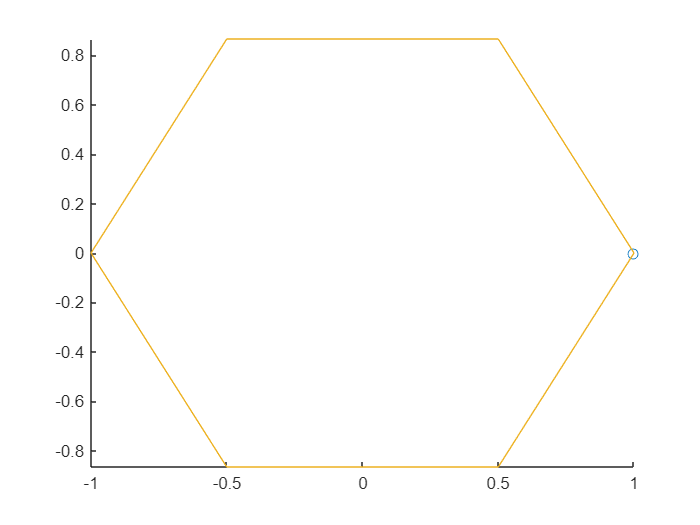


% Definimos los ángulos para un hexágono (6 lados)
theta2 = linspace(0, 2*pi, 7); % Se repite el primer punto para cerrar la figura
r2 = ones(size(theta2)); % Radio constante

% Convertimos a coordenadas cartesianas
x2 = r2 .* cos(theta2);
y2 = r2 .* sin(theta2);

% Graficamos la trayectoria
figure(2)
comet(x2, y2)

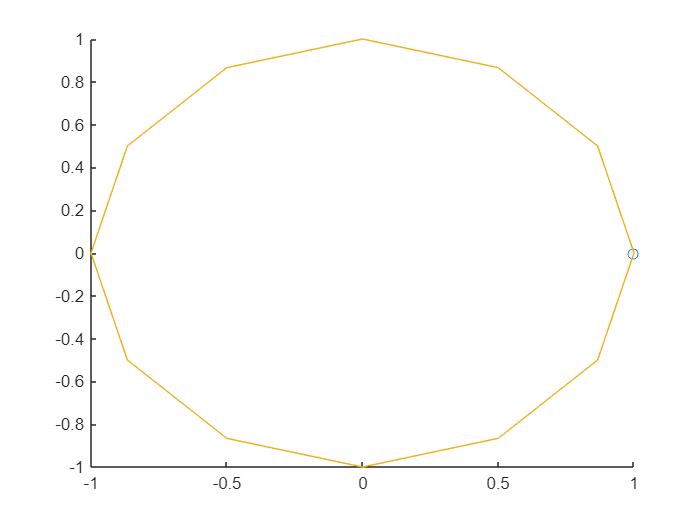


% Definimos los ángulos para un dodecágono (12 lados)
theta3 = linspace(0, 2*pi, 13); % Se repite el primer punto para cerrar la figura
r3 = ones(size(theta3)); % Radio constante

% Convertimos a coordenadas cartesianas
x3 = r3 .* cos(theta3);
y3 = r3 .* sin(theta3);

% Graficamos la trayectoria
figure(3)
comet(x3, y3)

Para esta parte el número de pétalos se ajusta modificando el valor del multiplicador  en la ecuación del radio. El programa convierte las coordenadas polares a cartesianas mediante las fórmulas x=r⋅cos (θ) y y=r⋅sin (θ), y luego grafica la flor con la función `comet`. Para cambiar el número de pétalos, basta con modificar el valor que multiplica a `anguloFlor` en la ecuación del radio.

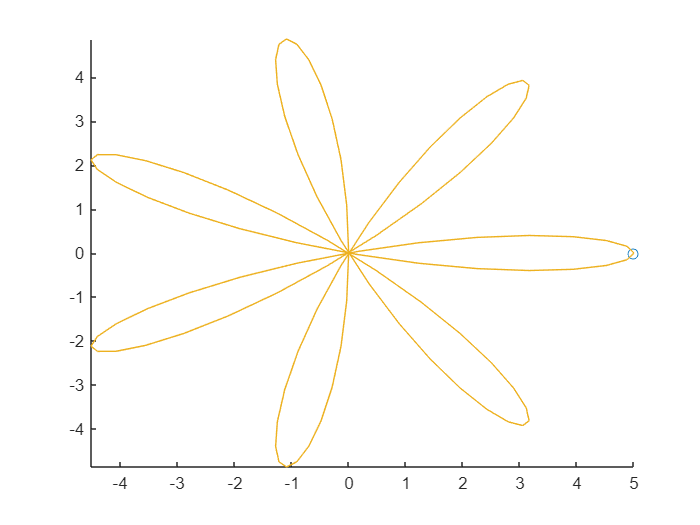

% Definimos el parámetro angular para la flor
anguloFlor = 0:pi/100:pi;  % Valores de theta para generar la figura

% Ecuación polar de la flor
radioFlor = 5 * cos(7 * anguloFlor);  % Radio variable con 7 pétalos

% Conversión a coordenadas cartesianas
coordX = radioFlor .* cos(anguloFlor);
coordY = radioFlor .* sin(anguloFlor);

% Graficación de la flor
figure(4)
comet(coordX, coordY)

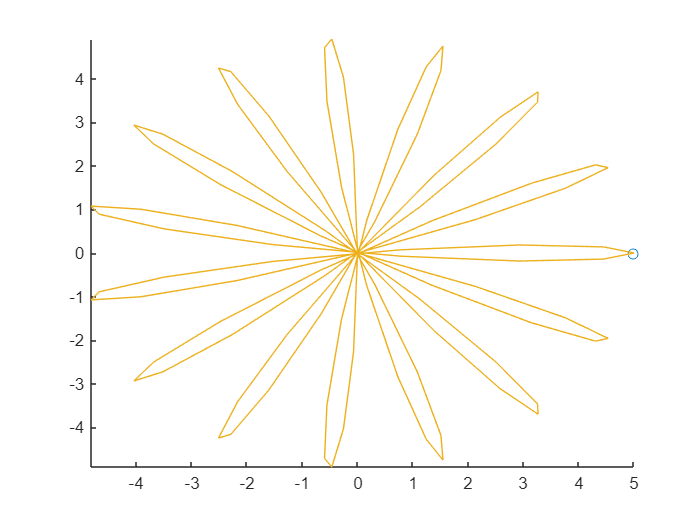

%%%%%%%
%Flor de 15 petalos
%Utilizamos el mismo rango angular
anguloFlor15=0:pi/100:pi;
radioFlor15=5*cos(15*anguloFlor15);

%conversion a coordenadas cartesianas
coordX15=radioFlor15.*cos(anguloFlor15);
coordy15=radioFlor15.*sin(anguloFlor15);

figure(5)
comet(coordX15,coordy15)

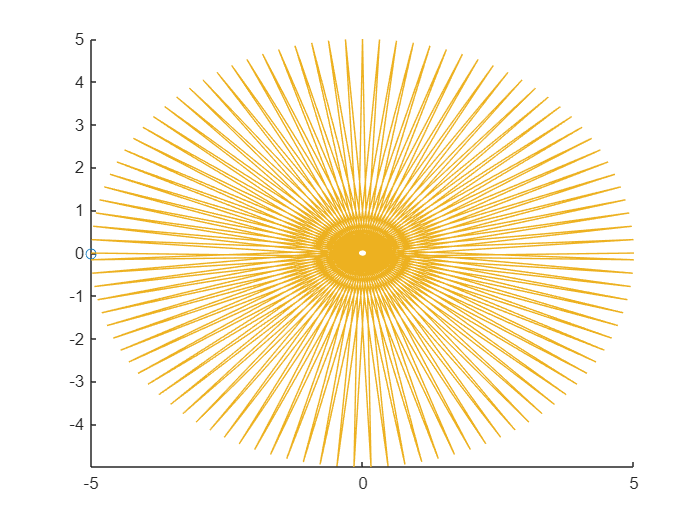

%%%%%%%%%%%%%%
% Configuración angular
anguloPetalos = 0:pi/100:pi;

% Patrón de pétalos densos
radioPetalos = 5 * cos(100 * anguloPetalos);

% Conversión de coordenadas polares a cartesianas
xCoordenadas = radioPetalos .* cos(anguloPetalos);
yCoordenadas = radioPetalos .* sin(anguloPetalos);

% Graficación final
figure(6)
comet(xCoordenadas, yCoordenadas)